# **Sample**

### **Importing shared dataset**

L = imread("cameraman.tif")

L = 256×256 uint8 matrix
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156   159   158   160   157   165   159   161   158   162   162   161   163   159   162   164   163   164   165   169   164   163   165   161   163   165   168   167   165   164   163   169   169   169   170   170   169   170   170
   156   159   158   155   158   156   159   158   157   158   158   159   160   160   160   158   163   161   162   160   164   160   165   163   161   163   161   164   165   162   161   165   165   164   166   165   164   166   167   165   165   164   170   166   167   167   170   168   169   166
   160   154   157   158   157   159   158   158   158   160   155   156

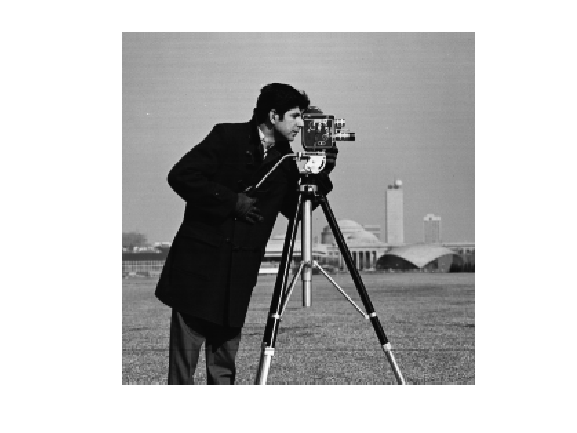

imshow(L)

### **Spatial Feature Extraction using MATLAB**


FeatureData = regionprops(L, 'all');

cor=corrcoef(L);

Error using  - 
Integers can only be combined with integers of the same class, or scalar doubles.

Error in cov (line 154)
xc = x - sum(x,1)./m;  % Remove mean

Error in corrcoef>correl (line 181)
r = cov(x);

Error in corrcoef (<a href="

FeatureData

FeatureData = 253×1 struct array with fields:
    Area
    Centroid
    BoundingBox
    SubarrayIdx
    MajorAxisLength
    MinorAxisLength
    Eccentricity
    Orientation
    ConvexHull
    ConvexImage
    ConvexArea
    Circularity
    Image
    FilledImage
    FilledArea
    EulerNumber
    Extrema
    EquivDiameter
    Solidity
    Extent
    PixelIdxList
    PixelList
    Perimeter
    PerimeterOld
    MaxFeretDiameter
    MaxFeretAngle
    MaxFeretCoordinates
    MinFeretDiameter
    MinFeretAngle
    MinFeretCoordinates


Area, BoundingBox, MajorAxisLength, MinorAxisLength, Eccentricity, Orientation, FilledArea, EulerArea, EquivDiameter, Solidity, perimeter

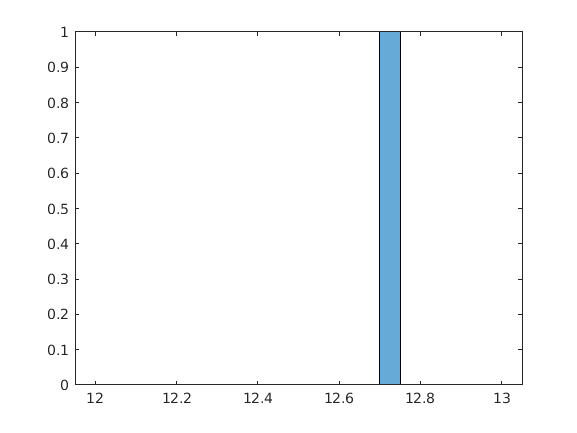

Array = [FeatureData.Perimeter];

Area_Min = min(Array);
Area_Max = max(Array);
Area_Mean = mean(Array);
Area_Std = std(Array);
Area_sk_=real(skewness(Array));
Area_ku_=real(kurtosis(Array));

figure('Name', 'histogram for area'), histogram(Array, 20);

Area_sk_

Area_sk_ = NaN

    
%Column Values
    rgb1=[r,g,b,av,med,st_dev,max_,min_,sk_,ku_,area,e,c_r_1,c_r_2,c_g_1,c_g_2,c_b_1,c_b_2,target];    
%Writing into Excel Sheets
    writematrix(rgb1,'test.csv','WriteMode', 'append');